# Lab 3

## FUNCTIONS

function m = my_mean(X)
    % Wrapper function for the median. Checks input shape and specifies the
    % dimension in which the median is calculated.
    % Output has the shape Bx1
    % Should work flawlessly (tested) for input shape 1xn, or 1xnxB

    if ndims(X) > 3
        error 'my_mean: The input has unexpected shape'
    end

    n = size(X, 2);
    X = reshape(X, 1, n, []);
    m = squeeze(mean(X, 2));
end

function med = my_median(X)
    % Wrapper function for the median. Checks input shape and specifies the
    % dimension in which the median is calculated.
    % Output has the shape Bx1
    % Should work flawlessly (tested) for input shape 1xn, or 1xnxB

    if ndims(X) > 3
        error 'my_median: The input has unexpected shape'
    end

    n = size(X, 2);
    X = reshape(X, 1, n, []);
    med = squeeze(median(X, 2));
end

function corr_coeff = my_corr(X)
    % Input X can be a matrix 2xn or 2xnxB
    % Output has the shape Bx1
    % Should work flawlessly (tested) for input shape 2xn or 2xnxB

    % check input shape
    if ismatrix(X)
        % if no B dimension, we append a singleton dimension so formulas
        % work the same (as if B was 1)
        [m, n] = size(X);
        X = reshape(X, m, n, 1);
    end
    if ndims(X) > 3
        error 'my_corr: The input has unexpected shape'
    end
    m = size(X,1);
    if m ~= 2
        error 'my_corr: The input should have two rows to compute the correlation'
    end
    % https://es.mathworks.com/matlabcentral/answers/15884-correlation-for-multi-dimensional-arrays#answer_21553
    % Compute correlations on second dimension
    % Remove means 
    az = bsxfun(@minus, X(1,:,:), mean(X(1,:,:), 2));
    bz = bsxfun(@minus, X(2,:,:), mean(X(2,:,:), 2));
    % Standard Pearson correlation coefficient formula
    a2 = az .^ 2;
    b2 = bz .^ 2;
    ab = az .* bz;
    corr_coeff = sum(ab, 2) ./ sqrt(sum(a2, 2) .* sum(b2, 2));
    corr_coeff = squeeze(corr_coeff);
end

function resample = boot_resample(X, B, dependency)
    % check input shape
    % dependency is a string that determines if there is any dependency
    %     between the rows of the data (if they have to be sampled by
    %     columns or the links should be broken).
    %     Options: 'dependent' or 'independent
    if ~ismatrix(X)
        error 'boot_resample: The input has unexpected shape'
    end
    [m, n] = size(X);
    if strcmp(dependency, 'independent')
        random_idxs = ceil(rand(m, n, B)*n);
        resample = random_idxs; % init for efficiency
        % sample row-wise differently
        for i=1:m
            resample(i,:,:) = reshape(X(i, random_idxs(i,:,:)), 1, n, B);
        end
    elseif strcmp(dependency, 'dependent')
        resample = reshape(X(:,ceil(rand(B, n)*n)), m, n, B);
    else
        error 'boot_resample: Input parameter 3 (dependency) not recognized'
    end
end

function ord_estimates = boot_resample_estimate(estimate, X, B, dependency)
    % computes the ordered bootstrap resample estimates
    % estimate is a callback function (e.g.: @my_median)
    % X is the input data, which is expected to have shape 1xn where n
    %     is the sample size
    % B is the resample size
    % output ord_estimates has shape Bxn
    % dependency is a string that determines if there is any dependency
    %     between the rows of the data (if they have to be sampled by
    %     columns or the links should be broken).
    %     Options: 'dependent' or 'independent

    if ~ismatrix(X)
        error 'boot_resample_estimate: The input has unexpected shape'
    end

    resample = boot_resample(X, B, dependency);
    ord_estimates = sort(estimate(resample), 1);
end

function ci = boot_percentiles_ci(estimate, X, B, alpha, corrected, dependency)
    % calculates the bootstrap percentiles confidence intervals
    % estimate is a callback function (e.g.: @my_median)
    % X is the input data, which is expected to have shape 1xn where n
    %     is the sample size
    % B is the resample size
    % alpha is 1 - the confidence level
    % corrected is a string that determines if the output interval is
    %     corrected or not. Options: 'corrected' or 'non-corrected'.
    % dependency is a string that determines if there is any dependency
    %     between the rows of the data (if they have to be sampled by
    %     columns or the links should be broken).
    %     Options: 'dependent' or 'independent
    pop_estimate = estimate(X);
    ord_boot_estimates = boot_resample_estimate(estimate, X, B, dependency);
    % TODO: CHECK CEIL AND FLOOR FORMULAS FOR LOW B VALUE
    est_low = ord_boot_estimates(ceil((B+1)*alpha/2)+1);
    est_high = ord_boot_estimates(floor((B+1)*(1-alpha/2)));
    if strcmp(corrected, 'corrected')
        ci = [2*pop_estimate - est_high, 2*pop_estimate - est_low];
    elseif strcmp(corrected, 'non-corrected')
        ci = [est_low, est_high];
    else
        error 'boot_percentiles_ci: Input parameter 5 (corrected) not recognized'
    end
end

function p = p_value(estimate, X, B, tails, dependency, normalize)
    % calculate the p-value using bootstrap replicates
    % estimate is a callback function (e.g.: @my_median)
    % X is the input data, which is expected to have shape 1xn where n
    %     is the sample size
    % B is the resample size
    % alpha is 1 - the confidence level
    % tails is a string that determines which test is done. Options:
    %     'left-tail', 'right-tail', 'two-tail'
    % dependency is a string that determines if there is any dependency
    %     between the rows of the data (if they have to be sampled by
    %     columns or the links should be broken).
    %     Options: 'dependent' or 'independent
    % normalize is a string that determines if the mean is normalized for
    %     the bootstrap resamples for computing the p-value (used to
    %     compare means, for instance). Options: 'mean'

    pop_estimate = estimate(X);

    if strcmp(normalize, 'mean')
        X = X - mean(X);
    else
        error 'p_value: Input parameter 6 (normalize) not recognized'
    end

    ord_boot_estimates = boot_resample_estimate(estimate, X, B, dependency);
    if strcmp(tails, 'two-tail')
        count = sum(abs(ord_boot_estimates) >= abs(pop_estimate));
    elseif strcmp(tails, 'left-tail')
        count = sum(ord_boot_estimates <= pop_estimate);
    elseif strcmp(tails, 'right-tail')
        count = sum(ord_boot_estimates >= pop_estimate);
    else
        error 'p_value: Input parameter 4 (tails) not recognized'
    end
    p = (count + 1) / (B + 1);
end

function bias = boot_bias(estimate, X, B, dependency)
    bias = mean(boot_resample_estimate(estimate, X, B, dependency)) - estimate(X);
end

function se = boot_std_err(estimate, X, B, dependency)
    se = std(boot_resample_estimate(estimate, X, B, dependency));
end

function ci = boot_studentized_ci(estimate, X, B, alpha, corrected, dependency, seed)
    pop_estimate = estimate(X);
    ord_boot_estimates = boot_resample_estimate(estimate, X, B, dependency);
    rng(seed);
    bias = boot_bias(@my_mean, ord_boot_estimates', B, 'independent');
    rng(seed);
    se = boot_std_err(@my_mean, ord_boot_estimates', B, 'independent');
    rng('shuffle');

    c = tinv(1-alpha/2, B-1); % n becomes B because we are 'estimating the estimator'

    if strcmp(corrected, 'corrected')
        ci = [pop_estimate - c*se, pop_estimate + c*se] - bias;
    elseif strcmp(corrected, 'non-corrected')
        ci = [pop_estimate - c*se, pop_estimate + c*se];
    else
        error 'boot_studentized_ci: Input parameter 5 (corrected) not recognized'
    end
end

## PROBLEM 3

Repeat Problem 2 but now use the computer to fully run the bootstrap algorithms for R = 999 replications.

Table 1 shows the marks for n = 5 students from 2 different Universities (A and B), on two aspects: science proficiency score and communication proficiency score. We wish to answer the following research question: on average, do students from University A perform differently than students from University B, in terms of those scores?

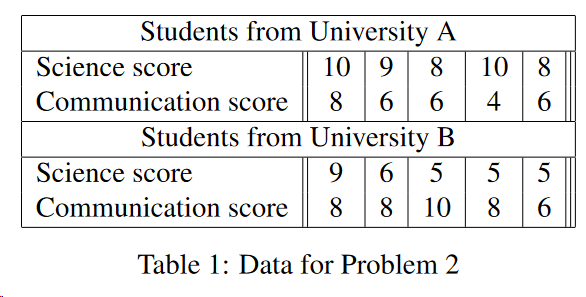

For this problem, we are only interested in the Science proficiency scores and we want to assess whether there is a difference in the median science scores of students when comparing both universities. For this we will use bootstrap. To avoid long calculations, you will assume that there is a large number (e.g. B = 9, 999) of bootstrap rounds, but you will compute explicitly only the first ten (10) rounds. For these R = 999 rounds, however, you must provide as much detail as you can1, for each of the following tasks:

x1 = [10 9 8 10 8; 8 6 6 4 6];
x2 = [9 6 5 5 5; 8 8 10 8 6];
X = cat(3, x1, x2);

**a) Use bootstrap to compute a 95% confidence interval for the difference of the median science scores of University A − University B.**

B = 999;
alpha = 0.05;
ci = boot_percentiles_ci(@my_median, X(1,:,1) - X(1,:,2), B, alpha, 'corrected', 'independent');
ci

ci =      1     5


**b) Use bootstrap to test the relevant null hypothesis for this problem.**

$\begin{cases}
      H_{0}: Med(A, Science) = Med(B, Science)\\
      H_{A}: Med(A, Science) \neq Med(B, Science)\\
\end{cases}$ , where $\textrm{Med}\left(A\;\textrm{or}\;B,\textrm{Science}\right)$ is the median of the Science grades for the populations of University A or B.

Since $0 \notin [1,5]$ we can reject the null hypothesis, that is, the median of the science grades of the University A are different than the ones from University B.

## PROBLEM 4

Use bootstrap to estimate a 90% confidence interval of the correlation coefficient between the two dimensions. Use B = 999.

B = 999;
alpha = 0.1;
X = [-6 -5 -2 3 5 7 6 2 -4 -7; -3 -2 -1 0 1 2 3 4 5 6];
ci = boot_percentiles_ci(@my_corr, X, B, alpha, 'corrected', 'dependent');
ci

ci =    -0.6482    0.7309


## PROBLEM 6

File SM22_Lab_3_Supermarket.xlsx contains more samples from the same supermarket data as Problem 5. In this case, however, there are n = 100 samples, and therefore we expect that the sample mean will have a distribution much closer to normal than in Problem 1.

**a) Generate R = 9999 bootstrap resamples from y.**

% Importing table
filename = 'resampling/lab3/SM22_Lab_3_Supermarket.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

**b) Use your bootstrap resamples to estimate the bias of **$s^2$

**c) Use your bootstrap resamples to estimate a 95% confidence interval for **$\sigma^2$

**d) Discuss how accurate you believe are your estimates in (b) and (c). Justify.**

## PROBLEM 10

Let x1 and x2 be two random samples, as follows:

x1 = [82 79 81 79 77 79 79 78 79 82 76 73 64];
x2 = [84 86 85 82 77 76 77 80 83 81 78 78 78];

We want to test if $\mu_1 =E\left\lbrack x_1 \right\rbrack$ is smaller than $\mu_2 =E\left\lbrack x_2 \right\rbrack$ at significance level α = 0.05 (where E[·] denotes expected value) and estimate the corresponding p-value.

**a) State the null and alternative hypotheses for this problem.**

$\begin{cases}
      H_{0}: \mu_1 = \mu_2\\
      H_{A}: \mu_1 < \mu_2\\
\end{cases}$ or equivalently $\begin{cases}
      H_{0}: \mu_1 - \mu_2 = 0\\
      H_{A}: \mu_1 - \mu_2 < 0\\
\end{cases}$ , where $\mu_i$ is the population mean for population $i$.

**b) Use bootstrapping to generate R = 1000 simulated resamples of x1 and x2. Use them to estimate the p-value of interest. What do you conclude about **$\mu_1$** < **$\mu_2$**?**

B = 1000;
alpha = 0.05;
p_val = p_value(@my_mean, x1-x2, B, 'left-tail', 'independent', 'mean')

p_val = 0.0190

Since the P-value of the difference between x1 and x2 is consistently smaller than alpha, we can conclude that we can reject the null hypothesis, that is, $\mu_1$ is smaller than $\mu_2$ with 95% confidence.

**c) Repeat (b), making sure that simulated resamples are not exactly the same as before (most random number generators do this by default unless you specify the same seed). Does your result coincide with (b)? - Explain why. (Hint: Results from (b) and (c) should NOT coincide exactly)**

p_val = p_value(@my_mean, x1-x2, B, 'left-tail', 'independent', 'mean')

p_val = 0.0120

It does not coincide exactly, however when $B\to \infty$ they should.

**d) Estimate a 95% confidence interval for your p-value. How does this affect your conclusion from (b) about **$\mu_1$** < **$\mu_2$**?**

ci = boot_percentiles_ci(@my_mean, x1-x2, B, alpha, 'corrected', 'independent')

ci =    -4.9231   -0.2308


Same result, $0\not\in \textrm{ci}$. Therefore we can reject the null hypothesis.

**e) Do you consider the results so far conclusive? If not, indicate what else could be done to obtain a more accurate p-value and report your revised results.**

Yes.

## PROBLEM 11

Consider again the data from the previous problem, but now as a bivariate sample (i.e. the two dimensions of a bivariate population X):

x1 = [82 79 81 79 77 79 79 78 79 82 76 73 64];
x2 = [84 86 85 82 77 76 77 80 83 81 78 78 78];
X = [x1; x2];

We wish to test whether the two dimensions of our hypothetical population X are correlated, at significance level α = 0.95. One possible approach to do so consists in computing a confidence interval for the correlation coefficient. We will use bootstrap for this:

**a) State the null and alternative hypotheses for this problem.**

$\begin{cases}
      H_{0}: \rho_{12} = 0\\
      H_{A}: \rho_{12} \neq 0\\
\end{cases}$ , where ${\rho \;}_{\textrm{xy}}$ is the population correlation coefficient between variables $x$ and $y$.

**b) Use bootstrapping to generate R = 1000 simulated resamples of x1 and x2. Use them to estimate the standard error and bias of the sample correlation.**

B = 1000;
alpha = 0.05;
seed = 1;
ord_boot_estimates = boot_resample_estimate(@my_corr, X, B, 'dependent');
rng(seed);
bias = boot_bias(@my_mean, ord_boot_estimates', B, 'independent')

bias = -1.7618e-05

rng(seed);
se = boot_std_err(@my_mean, ord_boot_estimates', B, 'independent')

se = 0.0045

rng('shuffle');

**c) Based on (b), estimate a 95% confidence interval for the correlation coefficient.**

ci = boot_percentiles_ci(@my_corr, X, B, alpha, 'corrected', 'dependent')

ci =     0.1410    0.6844


ci_estimator = boot_studentized_ci(@my_corr, X, B, alpha, 'corrected', 'dependent', seed)

ci_estimator =     0.4435    0.4617


**d) State your conclusions about the hypotheses from (a).**

We cannot reject the null hypothesis since the estimator accuracy is quite low. Even if the confidence interval for the correlation coefficient is above 0, the confidence interval for the estimator itself is quite high, making it possible that the confidence interval is above 0 because of noise.

## PROBLEM 12

Consider again data from Problem 10, and the same research question: are both dimensions correlated? Another way to address this question is by directly evaluating the null hypothesis (as opposed to the indirect way through the confidence intervals that we used in Problem 10).

**a) State the null and alternative hypotheses for this problem.**

**b) Use bootstrapping to generate R = 999 simulated resamples of x adequately modified so that the sampling process corresponds to the case in which the null hypothesis is true.**

**c) Based on (b), estimate a p-value for the hypotheses in (a) and state your conclusion.**

**d) Based on (b), we may also estimate a 95% confidence interval for the correlation coefficient under the null hypothesis. Explain where the interval is centered and what value shall we check against this interval to decide about the null.**

## PROBLEM 14

File SM22_Lab_3_Height_and_Weight.xlsx contains samples of height and weight from a set of individuals. Based on them, it is possible to estimate the Body Mass Index (BMI), which will be our variable of interest. BMI can be computed as follows:


$$\textrm{BMI}=\frac{\textrm{Weight}}{\textrm{Height²}}$$


Where $\textrm{Weight}$ must be expressed in kilograms and $\textrm{Height}$ in meters. If we compute BMI in this way, the distribution of our sample shows a rather large kurtosis, which is above 5. However, we wish to know how much we can trust the kurtosis value estimated from this sample, and thus we wish to estimate a confidence interval for it.

**a) Use bootstrapping to assess if the distribution of the sample kurtosis (You can look for the formula of the sample kurtosis or use existing functions to compute it.) can be assumed normal. Clearly indicate your conclusion.**

**b) Based on the bootstrap from (a), estimate the standard error and the bias of your estimator.**

**c) Estimate a 95% confidence interval for the kurtosis using student’s t. Based on your analysis from (b), discuss whether this is likely to be accurate or not.**

**d) Compute a 95% confidence interval for the kurtosis using the percentiles of the bootstrap distribution.**

## PROBLEM 15

File SM22_Lab_3_Marks.xlsx shows the marks from 32 students from statistical models in 2021 for labs 1 and 2. We wish to investigate whether students have, on average, improved their marks in Lab 2 with respect to Lab 1.

**a) State the null and alternative hypotheses for this problem.**

**b) Use bootstrapping to test the hypotheses defined in (a) at significance level α = 0.05. Report your estimated p-value and state your conclusion answering the research question. Hint: use at least B = 10,000 resamples.**

**c) Use bootstrapping to compute a 95% confidence interval of the average difference between the marks of labs 1 and 2. Analyze whether the conclusion from this interval confirms or contradicts your conclusion from (b).**

## PROBLEM 16

File SM22_Lab_3_Baseball.xlsx contains the salaries and batting averages of 50 randomly selected baseball players. We want to assess it there is a linear relationship (correlation) between the player salary and his performance (in this case, in terms of batting average).

**a) State the null and alternative hypotheses for this problem.**

**b) Use bootstrapping to test the hypotheses defined in (a) at significance level α = 0.05. Report your estimated p-value and state your conclusion answering the research question.**

**c) Use bootstrapping to compute a 95% confidence interval of the correlation coefficient between salaries and batting averages. Analyze whether the conclusion from this interval confirms or contradicts your conclusion from (b).**

## PROBLEM 17

Incumbent local exchange carriers (ILECs) install and maintain local telephone lines, lease capacity, and perform repairs for the competing local exchange carriers (CLECs). File SM22_Lab_3_ILEC_1.xlsx provides the random sample x2 corresponding to the repair times (in hours) of 1664 service requests from customers of an ILEC and file SM22_Lab_3_ILEC_2.xlsx provides x2 corresponding to 23 requests from customers of a CLEC during the same time period.

**a) Assess whether these two random samples seem to come from normal distributions.**

**b) Use bootstrapping to generate a simulated population of random resamples that allows you to inspect the distribution of the statistic t = x1 − x2.**

**c) Estimate the bias of t = x1 − x2.**

**d) Compute a 95% confidence interval for t based on the percentiles of the bootstrap distribution. Based on the analysis from (a) and (b) discuss whether this interval seems appropriate.**

**e) Based on your answers to (b) and (d), what can you conclude about the statement following statement: "repair times for ILEC customers are significantly smaller than repair times for CLEC customers".**

## PROBLEM 18

File SM22_Lab_3_3D.xlsx contains a random sample from some tri-dimensional data. We are interested in assessing how dominant is the first principal component of the data, for which we choose the statistic t to be the ratio between the largest and second-largest eigenvalues of the covariance matrix of our random sample. That is, if $\lambda_1 \ge \lambda_2 \ge \lambda_3$ are the eigenvalues of the sample covariance matrix, we want a 95% confidence interval for


$$t=\frac{\lambda_1 }{\lambda_2 }$$


Analyze the data carefully and justify the method chosen to estimate the requested interval.

## PROBLEM 19

Last year, in Lab 1, we analyzed the concentration of 5 contaminants in salmon samples from different origins. For simplicity, file SM22_Lab_1_Salmon2.xlsx is provided again here with the same data. When we analyzed salmon from Scotland, there was large consensus from a majority of students that we could not reject univariate normality for any of the dimensions (contaminants). How-

ever, the conclusions about bivariate normality were less clear, given that the chi-square plots for some pairs of dimensions showed deviations from the expected behavior for normality from which it was not trivial to decide whether we shall or shall not reject normality.

In this problem we will re-analyze the samples of salmon from Scotland and will assess bi-variate normality quantitatively with the help of parametric bootstrap. To this end, we will use two statistics to evaluate how much a chi-square plot deviates from bivariate normality: i) the correlation coefficient (similarly to what we do for qq-plots) and ii) the slope of the resulting plot (The slope of a linear approximation of our resulting plot.).

**a) Use parametric bootstrapping to generate B replicates (Choose an adequately large value for B.) of the two statistics indicated above, under the null hypothesis H0: the population from which we sample our bootstraps follows a bivariate normal distribution. Plot the resulting replicates together (For example, you can use a scatter plot or a density estimate.) as the two dimensions of a single 2-dimensional statistic ˆθ. Keep in mind that these are replicates intended to assess bivariate normality of our sample from Scotish salmon.**

**b) Assess whether the distribution of the replicates from ˆθ generated in (a) can be considered multivariate normal. Clearly indicate your conclusion.**

**c) Since our statistic ˆθ is bi-dimensional, we may compute simultaneous confidence intervals that should be fulfilled by a given chi-square plot if it comes from a bivariate normal distribution (at a given significance level). Compute such intervals for significance level α = 0.05. Hint: analyze carefully what would be the expected behavior under normality to determine whether each of the intervals shall be one- or two-sided. Justify adequately.**

**d) Use the intervals obtained in (c) to analyze bivariate normality of all possible pairs of contaminants in the dataset of salmon from Scotland. Clearly indicate your conclusions.**